In =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$q1 = \frac{R^{2}\,g^{2}\,m}{V^{2}\,c}$$

$$q2 = -\frac{2\,R\,g}{V}$$

$$q3 = -\frac{R}{L}$$

$$q4 = \frac{1}{L}$$

$$q1 = 630.0$$

$$q2 = -5.1$$

$$q3 = -\frac{554}{13}$$

$$q4 = \frac{20}{13}$$

A =                          0                         0                         1                         0
                         0           629.09300494194                         0         -5.12711320724338
                         0                         0                         0         -42.6153846159577


B =                          0
                         0
          1.53846153849736


C =      1     0     0


Aa =                          0                        -1                         0                         0
                         0                         0                         1                         0
                         0           629.09300494194                         0         -5.12711320724338
                         0                         0                         0         -42.6153846159577


Ba =                          0
                         0
                         0
          1.53846153849736


Mc =                          0                         0                         0          7.88786647286578
                         0                         0         -7.88786647286578          336.144463540493
                         0         -7.88786647286578          336.144463540493         -19287.1272222988
          1.53846153849736          -65.562130179923          2793.95539385891         -119065.483709127


ans =           755.031887865464


M =                          0                         0                         0          7.88786647286578
                         0                         0         -7.88786647286578          336.144463540493
                         0         -7.88786647286578          336.144463540493         -19287.1272222988
          1.53846153849736          -65.562130179923          2793.95539385891         -119065.483709127


$$pc = -1.8e-15\,\left(1.3e+8\,s+5.7e+9\right)\,\left(2.6e+9\,s-4.2e+6\,s^{3}\right)$$

polyPc =                          1          42.6153846159577          -629.09300494194         -26809.0403648094                         0


W =          -26809.0403648094          -629.09300494194          42.6153846159577                         1
          -629.09300494194          42.6153846159577                         1                         0
          42.6153846159577                         1                         0                         0
                         1                         0                         0                         0


T =           7.88786647286578                         0                         0                         0
                         0         -7.88786647286578                         0                         0
                         0                         0         -7.88786647286578                         0
      1.45519152283669e-11         -967.835392240904                         0          1.53846153849736


$$pi = s^{4}+13\,s^{3}+54\,s^{2}+82\,s+60$$

polyPi =      1    13    54    82    60


K =           7.60661963620705          -1047.2044744495         -86.6004777453798         -19.2499999999243


p =                          0
          25.0817265143758
         -25.0817265143758
         -42.6153846159577


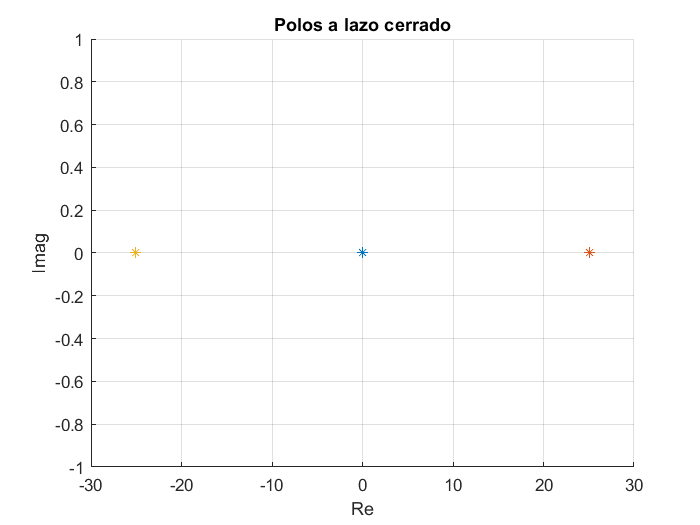

p =          -0.999999999997465 +      1.00000000000591i
         -0.999999999997465 -      1.00000000000591i
          -5.00000000001351 +                     0i
          -5.99999999999154 +                     0i


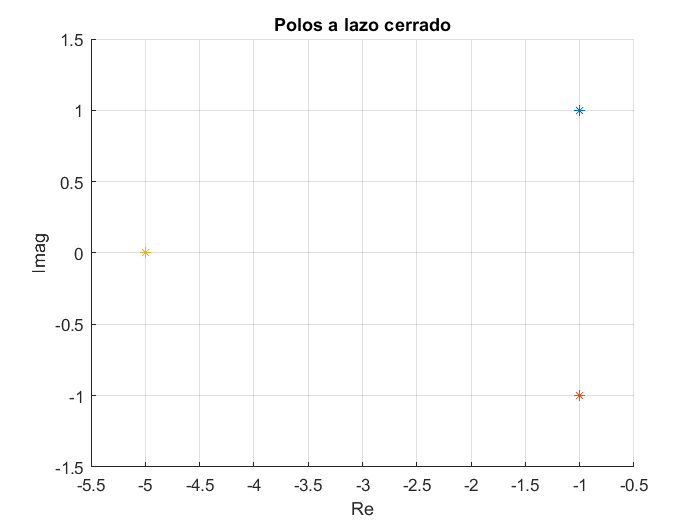

% definimos la variable compleja s
format longG
syms s c m R g L V x1 x2 x3 X1 X2 X3 k1 k2 k3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0 0;0 1 0 0;0 0 1 0; 0 0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]


% Se sustituyeron los valores netos de
% http://dx.doi.org/10.1080/00207729608929322 
% R = 27.7 Ohm , L = 0.65 H, c = 1.24 * 10^-4 Nm^2 A^2, M =11.87gr=0.01187Kg, 
% se variara la tensión del punto de equilibrio de 106,02V a 111,97V, lo
% cual deberia permitir tener un control robusto de la planta para
% posiciones entre 15,6mm a 17.4mm

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2)
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)))
%q3 A(3,3)
q3 = -R/L
%q4 B(3,1)
q4 = 1/L

% Sustituimos los valores por defecto 

q1 = vpa(subs(q1, [c g m R V], [1.24e-4 9.81 0.01187 27.7 106]), 2)

q2 = vpa(subs(q2, [c g m R V], [1.24e-4 9.81 0.01187 27.7 106]), 2)

q3 = subs(q3, [R L], [27.7 0.65])

q4 = subs(q4, L, 0.65)

%planta
A=[0 0 1 0;0 double(vpa(q1,2)) 0 double(vpa(q2,2));0 0 0 double(vpa(q3,2))]

B=[0; 0; double(vpa(q4,2))]

C=[1 0 0]

% Sistema aumentado 

Aa = [0 -C; A]
Ba = [0; B]

% Controlabilidad

Mc = [Ba Aa*Ba Aa^2*Ba Aa^3*Ba]
det(Mc)
% Buscamos el valor K tal que u=-Kx

% T = MW

M = [Ba, Aa*Ba, Aa^2*Ba, Aa^3*Ba]

% polinomio caracteristico

pc = vpa(det(s*In - Aa), 2)
% polinomio en forma de array
polyPc = sym2poly(pc)

% W

W = [polyPc(4), polyPc(3), polyPc(2), 1; polyPc(3), polyPc(2), polyPc(1) 0;polyPc(2), polyPc(1), 0, 0;1, 0, 0, 0]

% T

T = M*W

% polinomio de interes 

pi = expand((s+1-1i)*(s+1+1i)*(s+5)*(s+6))

polyPi = sym2poly(pi)

% determinamos K

K = [polyPi(5)-polyPc(5), polyPi(4)-polyPc(4), polyPi(3)-polyPc(3), polyPi(2)-polyPc(2)] * inv(T)

% K = [k1, k2, k3]
% eq1 = det(s*In - A + B*K)
% eq2 = (s-1+i)*(s-1-i)*(s-5)
% expand(eq2)
% vpa(eq1,2) 

% graficamos los polos a lazo abierto

figure

p=eig(Aa)
hold on
plot(real(p(1)),imag(p(1)),'*')
plot(real(p(2)),imag(p(2)),'*')
plot(real(p(3)), imag(p(3)), '*')

grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off


figure

p=eig(Aa- Ba* K)
hold on
plot(real(p(1)),imag(p(1)),'*')
plot(real(p(2)),imag(p(2)),'*')
plot(real(p(3)), imag(p(3)), '*')

grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off
